# Rock vs No Rock: Data recording sheet

Author: Ross Wilkinson

University: University of Colorado Boulder

## Testing information

- Experiment: Rock vs No Rock

- Objective: Test effect of bicycle lean on maximal power output 

- Date: September 10, 2020

- Location: Locomotion Laboratory

- Subject: TM

- Quarq calibration factor: 

## Experimental setup

### Protocol reminders

- Charge Garmin, iPad, and IMUs

- Clarify participant understanding and answer questions

- Set saddle height and handlebar position

- Sanitize bicycle

- Calibrate power meter

- Setup cooling fan

- Gift card and signature

### Experimental conditions

- Preferred Lean

- Self-restricted

- Locked

### Trial order

- Warm up: 5 min at ~100 W (3.5 lb)

- Familiarization: Standing and leaning (8.5 lb)

- Pmax Test: 3 x hanging weights under condition 1

- Block 1: Randomize

- Block 2: Randomize

- Block 3: Randomize

### Environmental conditions

- Temperature (C): 21.6

- Humidity (%): 33 

- Pressure (mmHg): 636            

- Altitude (m): 1641

### Subject characteristics

Record subject characteristics to table for group data analysis.

number = 8;
code = {'TM'};
sex = {'M'};
age = 34;
mass = 180; %lb
height = 1.83; %m

T = table(number,code,sex,age,mass,height)

T = 1×6 table
    number     code      sex     age    mass    height
    ______    ______    _____    ___    ____    ______

      8       {'TM'}    {'M'}    34     180      1.83 


## Results

Use mass to calculate individualised hanging weights for Pmax Test.

listPerc = [0.06; 0.12; 0.18];
listHang = listPerc * mass

listHang =    10.8000
   21.6000
   32.4000


### Pmax test

Record Pmax test results. Fit curve to predict optimal hanging weight.

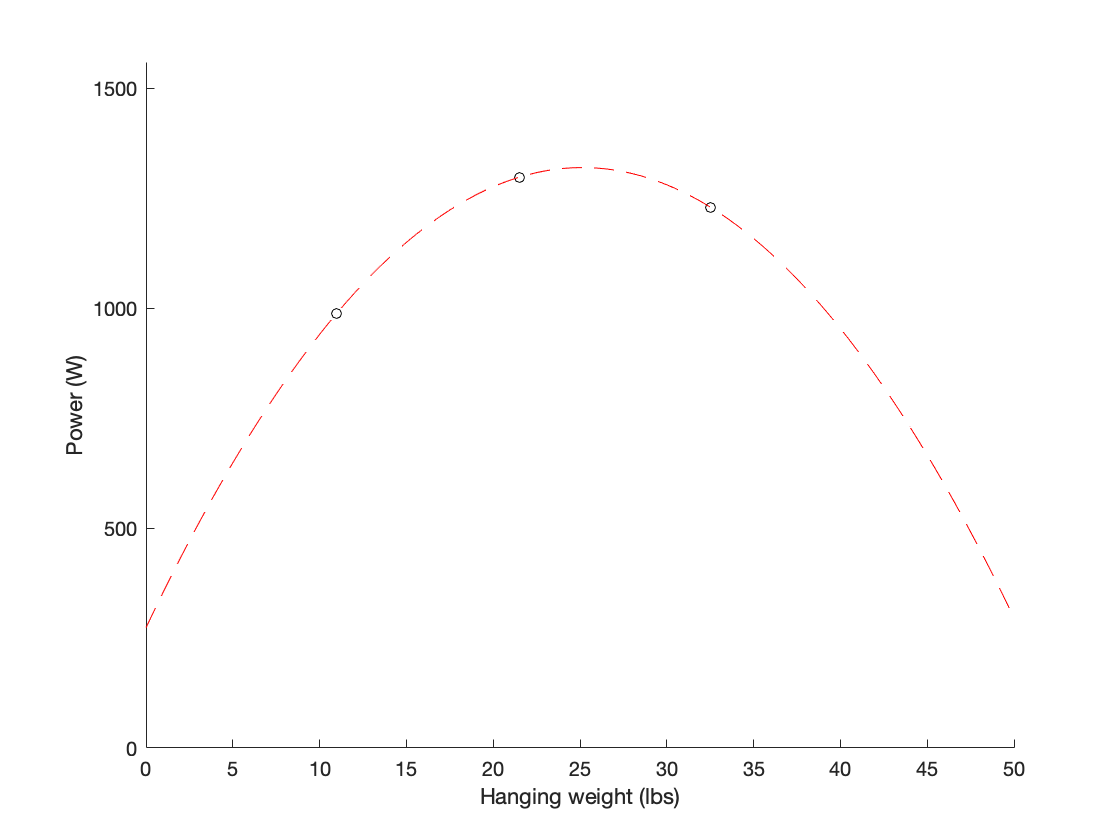

x = [11; 21.5; 32.5]; % hanging weight
x_ = [168; 124; 95]; % cadence
y = [989; 1298; 1230]; % power output

% fit curve: power vs hang
% [c, ~, ~] = fit(x,y,'poly2','Lower',[-Inf -Inf 0],'Upper',[Inf Inf 0]);
[c, ~, ~] = fit(x,y,'poly2');

new_x = 0:50/100:50;
new_y = c.p1*new_x.^2+c.p2*new_x+c.p3;

% plot curve: power vs hang
scatter(x,y,25,'k');
hold on
plot(new_x,new_y,'r--')

% edit figure
box off
xlabel('Hanging weight (lbs)')
ylabel('Power (W)')
xlim([0 50])
ylim([0 max(y)*1.2])


% find optimal x and y
[yOpt,I] = max(new_y);
xOpt = new_x(I);

fprintf('Predicted maximal power output = %4.2f Watts \n', yOpt)

Predicted maximal power output = 1319.84 Watts 


fprintf('Predicted optimal hanging weight = %4.2f Lbs \n', xOpt)

Predicted optimal hanging weight = 25.00 Lbs 


### Randomize trial order within each block

randperm(3)

ans =      2     3     1


randperm(3)

ans =      3     2     1


randperm(3)

ans =      2     3     1


### Experimental results

Record results to array then convert to table.

data = [
    8, 1, 1, 25, 1414, 118; 
    8, 2, 1, 25, 1408, 116; 
    8, 3, 1, 25, 1468, 123;
    8, 2, 2, 25, 1383, 116;
    8, 3, 2, 25, 1408, 123;
    8, 1, 2, 25, 1391, 119;
    8, 3, 3, 25, 1360, 120;
    8, 1, 3, 25, 1396, 120;
    8, 2, 3, 25, 1396, 118;
    ];

T_ = array2table(data, ...
    'VariableNames',{'subject','condition','trial','hangingWeight','power','cadence'})

T_ = 9×6 table
    subject    condition    trial    hangingWeight    power    cadence
    _______    _________    _____    _____________    _____    _______

       8           1          1           25          1414       118  
       8           2          1           25          1408       116  
       8           3          1           25          1468       123  
       8           2          2           25          1383       116  
       8           3          2           25          1408       123  
       8           1          2           25          1391       119  
       8           3          3           25          1360       120  
       8           1          3           25          1396       120  
       8           2          3           25          1396       118  

## Data analysis

Calculate mean and SD power and cadence for experimental trials.

varfun(@mean,T_,'InputVariables',{'power','cadence'}, ...
    'GroupingVariables',{'condition'})

ans = 3×4 table
    condition    GroupCount    mean_power    mean_cadence
    _________    __________    __________    ____________

        1            3           1400.3            119   
        2            3           1395.7         116.67   
        3            3             1412            122   


varfun(@std,T_,'InputVariables',{'power','cadence'}, ...
    'GroupingVariables',{'condition'})

ans = 3×4 table
    condition    GroupCount    std_power    std_cadence
    _________    __________    _________    ___________

        1            3          12.097             1   
        2            3          12.503        1.1547   
        3            3          54.111        1.7321   
